Load the data.

(given script)

loaddata

../Data/ACTOBS_S01_20161109_1108.mat
../Data/ACTOBS_S02_20161207-1002.mat
../Data/ACTOBS_S03_20161122-1529.mat
../Data/ACTOBS_S04_20161125-1211.mat
../Data/ACTOBS_S05_20161118_1339.mat
../Data/ACTOBS_S06_20161125-1033.mat
../Data/ACTOBS_S07_20161202-1521.mat
../Data/ACTOBS_S08_20161207-1434.mat
../Data/ACTOBS_S09_20161209-0958.mat
../Data/ACTOBS_S10_20161215-1615.mat
../Data/ACTOBS_S11_20161216-1131.mat
../Data/ACTOBS_S12_20161222-1036.mat
../Data/ACTOBS_S13_20161222-1406.mat
../Data/ACTOBS_S14_20170106-1517.mat
../Data/ACTOBS_S15_20170203-1237.mat
    flipped responses for block 1!
../Data/ACTOBS_S16_20170110-1509.mat
../Data/ACTOBS_S17_20170117-1048.mat
../Data/ACTOBS_S18_20170127-1459.mat
../Data/ACTOBS_S20_20170202-1235.mat
../Data/ACTOBS_S21_20170208-1404.mat
../Data/ACTOBS_S22_20170209-1228.mat
../Data/ACTOBS_S23_20170210-0956.mat
../Data/ACTOBS_S24_20170215-1430.mat
../Data/ACTOBS_S25_20170216-1146.mat
../Data/ACTOBS_S26_20170306-1121.mat
../Data/ACTOBS_S27_20170228-1126.mat
../


dout = '../Out/' % folder for produced data

dout = '../Out/'

Inital fits ('nrep' number of fits) of the actual data to obtain an estimate of the two variables of interest, the probability of reversal (prev) and the choice variability (beta), that will serve fixed refence values to the next analyses.

nrep = 10;

clear prev_fit beta_fit % to prevent any dimension error when using MATLAB LiveScript environment 
[prev_fit, beta_fit] = initialfit(nrep, nsubj, dat, subjlist);

mean_prev_fit = mean(prev_fit(:))

mean_prev_fit = 0.2087

mean_beta_fit = mean(beta_fit(:))

mean_beta_fit = 1.2439

Using a (given) function "sim_model_softmax", dataset are simulated using the fixed parameters (nsim simulated datasets).

nsim              = 30;                % number of simulations
nttest            = 100;               % number of ttests
ndiff             = [0      0   ; ...
                     0.01   0   ; ...
                     0.02   0   ; ...
                     0.03   0   ; ...
                     0.04   0   ; ...
                     0.05   0   ; ...
                     0.1    0   ; ...
                     0      0.1 ; ...
                     0      0.2 ; ...
                     0      0.3 ; ...
                     0      0.4 ; ...
                     0      0.5 ; ...
                     0      1   ]     % couples of differences to be tested

ndiff =          0         0
    0.0100         0
    0.0200         0
    0.0300         0
    0.0400         0
    0.0500         0
    0.1000         0
         0    0.1000
         0    0.2000
         0    0.3000


nsubjsubset       = [24]              % subset(s) of participants (w/out consideration for medical condition, 96 = all)

nsubjsubset = 24


% preallocation
prev_diffsigni_acrossdiff = zeros(1, 2, length(nsubjsubset), 1); % significant ttest counter across the differences tested
beta_diffsigni_acrossdiff = zeros(1, 2, length(nsubjsubset), 1);

revindexdiff = 0 % initilisation of difference counter

revindexdiff = 0

for idiff = ndiff'
    revindexdiff = revindexdiff+1; % to facilitate iteration of the differences outside the loop
    
    idiff % to display the difference being computed in MATLAB LiveScript environment 
    prev_fix = [mean_prev_fit-(idiff(1)/2) mean_prev_fit+(idiff(1)/2)]
    beta_fix = [mean_beta_fit-(idiff(2)/2) mean_beta_fit+(idiff(2)/2)]
    
    % preallocation
    prev_ttest = zeros(nttest, 5, length(nsubjsubset)); % ttest results saved
    beta_ttest = zeros(nttest, 5, length(nsubjsubset));
    
    prev_diffsigni = zeros(1, 2, length(nsubjsubset)); % significant ttest counter
    beta_diffsigni = zeros(1, 2, length(nsubjsubset));
    
    for isubjsubset = nsubjsubset
            % preallocation
            prev_recov = zeros(isubjsubset,2,nsim);
            beta_recov = zeros(isubjsubset,2,nsim);
            
            isubjsubset % to display the current subset running in MATLAB LiveScript environment 
            seq_isubjsubsest = randperm(nsubj,isubjsubset) % to avoid selecting deterministically the same subjects across subsets
        for ittest = 1:nttest
            for isubj = seq_isubjsubsest
            % given script -->
                for itask = 1:2
                    
                    % filter trials of interest
                    ifilt = dat.subj == subjlist(isubj) & dat.task == itask;
                    
                    % simulate model
                    cfg_sim        = [];
                    cfg_sim.nsim   = nsim;
                    cfg_sim.seqllr = dat.evid(ifilt);
                    cfg_sim.seqind = dat.sind(ifilt);
                    cfg_sim.prev   = prev_fix(itask);
                    cfg_sim.beta   = beta_fix(itask);
                    cfg_sim.brep   = 0; % force no repetition bias
                    cfg_sim.epsi   = 0; % force no lapses
                    
                    out_sim        = sim_model_softmax(cfg_sim);
                

        Then each datasets is fit using the (given) function "fit_model_softmax".

                    % fit simulated decisions
                    for isim = 1:nsim
                        cfg_fit        = [];
                        cfg_fit.seqllr = out_sim.cfg.seqllr;
                        cfg_fit.seqind = out_sim.cfg.seqind;
                        cfg_fit.raft   = out_sim.raft(:,isim);
                        cfg_fit.rbef   = out_sim.rbef(:,isim);
                        cfg_fit.brep   = out_sim.cfg.brep; % force no repetition bias
                        cfg_fit.epsi   = out_sim.cfg.epsi; % force no lapses
                            
                        out_recov = fit_model_softmax(cfg_fit);
            % <-- given script                        

        Estimated value of prev and beta from each simulation are stored and their average value is computed.

                        % store model parameters
                        revindexsubj = find(seq_isubjsubsest==isubj); % isubj goes over the index limit due to the 
                                                                      % use of subsets --> reverse indexing
                        prev_recov(revindexsubj,itask,isim) = out_recov.prev;
                        beta_recov(revindexsubj,itask,isim) = out_recov.beta;
                    end    
                end
            end

        Paired-sample t-test + data saving for each given difference (ndiff)

            revindexsubset = find(nsubjsubset==isubjsubset);    
            
            [h,p,ci,stats] = ttest(prev_recov(1,1,:),prev_recov(1,2,:));
            prev_ttest(ittest, 1, revindexsubset) = h;
            prev_ttest(ittest, 2, revindexsubset) = p;
            prev_ttest(ittest, 3, revindexsubset) = ci(:,:,1);
            prev_ttest(ittest, 4, revindexsubset) = ci(:,:,2);
            prev_ttest(ittest, 5, revindexsubset) = stats.sd;
            
            [h,p,ci,stats] = ttest(beta_recov(1,1,:),beta_recov(1,2,:));
            beta_ttest(ittest, 1, revindexsubset) = h;
            beta_ttest(ittest, 2, revindexsubset) = p;
            beta_ttest(ittest, 3, revindexsubset) = ci(:,:,1);
            beta_ttest(ittest, 4, revindexsubset) = ci(:,:,2);
            beta_ttest(ittest, 5, revindexsubset) = stats.sd;
            
        end
        
        prev_diffsigni(:,:,revindexsubset) = [length(find(prev_ttest(:,1,revindexsubset) == 1)) nttest]; %ttest counter
        beta_diffsigni(:,:,revindexsubset) = [length(find(beta_ttest(:,1,revindexsubset) == 1)) nttest];
        
        
    end
    
    prev_diffsigni_acrossdiff(:,:,:,revindexdiff) = prev_diffsigni % to save data across differences tested
    beta_diffsigni_acrossdiff(:,:,:,revindexdiff) = beta_diffsigni % displayed in MATLAB LiveScript environment
    
    str_nsubjsubset = ''; % to nicely convert nsubjsubset into a string, e.g., "12-24-48-96"
    for isubjsubset = nsubjsubset
        str_nsubjsubset = [str_nsubjsubset, num2str(isubjsubset),'-'];
    end
    str_nsubjsubset = str_nsubjsubset(1:end-1) % to delete the last (useless) '-'
    
    formatSpec_file = '%s%s_(%g-%g)diff_%ssubj_%dx%dsim.mat';
    
    name_prev_ttest = sprintf(formatSpec_file, dout,'prev_ttest',idiff(1),idiff(2),str_nsubjsubset,nttest,nsim);
    save(name_prev_ttest, 'idiff','nsubjsubset','nsim','nttest','prev_ttest','prev_diffsigni')
    
    name_beta_ttest = sprintf(formatSpec_file, dout,'beta_ttest',idiff(1),idiff(2),str_nsubjsubset,nttest,nsim);
    save(name_beta_ttest, 'idiff','nsubjsubset','nsim','nttest','beta_ttest','beta_diffsigni')
      
end

idiff =      0
     0


prev_fix =     0.2087    0.2087


beta_fix =     1.2439    1.2439


isubjsubset = 24

seq_isubjsubsest =     21    32    78    59    90    74    43    30    63    39    84    40    73    55     5    89    34    50    49     8     7    71    17    26


prev_diffsigni_acrossdiff =      8   100


beta_diffsigni_acrossdiff =      4   100


str_nsubjsubset = '24'

idiff =     0.0100
         0


prev_fix =     0.2037    0.2137


beta_fix =     1.2439    1.2439


isubjsubset = 24

seq_isubjsubsest =     85    82    40    19    79    11    83    68    67    91    32    49     7    77    56    16    63    89    29    31    14    21    34    94


prev_diffsigni_acrossdiff = prev_diffsigni_acrossdiff(:,:,1,1) =

     8   100


prev_diffsigni_acrossdiff(:,:,1,2) =

    13   100


beta_diffsigni_acrossdiff = beta_diffsigni_acrossdiff(:,:,1,1) =

     4   100


beta_diffsigni_acrossdiff(:,:,1,2) =

     5   100


str_nsubjsubset = '24'

idiff =     0.0200
         0


prev_fix =     0.1987    0.2187


beta_fix =     1.2439    1.2439


isubjsubset = 24

seq_isubjsubsest =     94    32    22    52    55    13    53    66    26     8    23    34    51    78    18    89    25    96    46     2    56    42     3    38


prev_diffsigni_acrossdiff = prev_diffsigni_acrossdiff(:,:,1,1) =

     8   100


prev_diffsigni_acrossdiff(:,:,1,2) =

    13   100


prev_diffsigni_acrossdiff(:,:,1,3) =

    26   100


beta_diffsigni_acrossdiff = beta_diffsigni_acrossdiff(:,:,1,1) =

     4   100


beta_diffsigni_acrossdiff(:,:,1,2) =

     5   100


beta_diffsigni_acrossdiff(:,:,1,3) =

     7   100


str_nsubjsubset = '24'

idiff =     0.0300
         0


prev_fix =     0.1937    0.2237


beta_fix =     1.2439    1.2439


isubjsubset = 24

seq_isubjsubsest =     89     9    16    51     8    29    15    54    76    42    50    19    18    82    59     6    39    69    27    25    38    13    17     2


prev_diffsigni_acrossdiff = prev_diffsigni_acrossdiff(:,:,1,1) =

     8   100


prev_diffsigni_acrossdiff(:,:,1,2) =

    13   100


prev_diffsigni_acrossdiff(:,:,1,3) =

    26   100


prev_diffsigni_acrossdiff(:,:,1,4) =

    51   100


beta_diffsigni_acrossdiff = beta_diffsigni_acrossdiff(:,:,1,1) =

     4   100


beta_diffsigni_acrossdiff(:,:,1,2) =

     5   100


beta_diffsigni_acrossdiff(:,:,1,3) =

     7   100


beta_diffsigni_acrossdiff(:,:,1,4) =

     5   100


str_nsubjsubset = '24'

idiff =     0.0400
         0


prev_fix =     0.1887    0.2287


beta_fix =     1.2439    1.2439


isubjsubset = 24

seq_isubjsubsest =     65     2    47    70    74    84    44    55    54     3    71     8    75    26    93    35    92    49    78    32    17    23    61    42


prev_diffsigni_acrossdiff = prev_diffsigni_acrossdiff(:,:,1,1) =

     8   100


prev_diffsigni_acrossdiff(:,:,1,2) =

    13   100


prev_diffsigni_acrossdiff(:,:,1,3) =

    26   100


prev_diffsigni_acrossdiff(:,:,1,4) =

    51   100


prev_diffsigni_acrossdiff(:,:,1,5) =

    78   100


beta_diffsigni_acrossdiff = beta_diffsigni_acrossdiff(:,:,1,1) =

     4   100


beta_diffsigni_acrossdiff(:,:,1,2) =

     5   100


beta_diffsigni_acrossdiff(:,:,1,3) =

     7   100


beta_diffsigni_acrossdiff(:,:,1,4) =

     5   100


beta_diffsigni_acrossdiff(:,:,1,5) =

    10   100


str_nsubjsubset = '24'

idiff =     0.0500
         0


prev_fix =     0.1837    0.2337


beta_fix =     1.2439    1.2439


isubjsubset = 24

seq_isubjsubsest =     73    80    12    51    23    74    18    41    56    81    20    76    40    22     3    39    70    94    71    84    11    69    45    46


prev_diffsigni_acrossdiff = prev_diffsigni_acrossdiff(:,:,1,1) =

     8   100


prev_diffsigni_acrossdiff(:,:,1,2) =

    13   100


prev_diffsigni_acrossdiff(:,:,1,3) =

    26   100


prev_diffsigni_acrossdiff(:,:,1,4) =

    51   100


prev_diffsigni_acrossdiff(:,:,1,5) =

    78   100


prev_diffsigni_acrossdiff(:,:,1,6) =

    93   100


beta_diffsigni_acrossdiff = beta_diffsigni_acrossdiff(:,:,1,1) =

     4   100


beta_diffsigni_acrossdiff(:,:,1,2) =

     5   100


beta_diffsigni_acrossdiff(:,:,1,3) =

     7   100


beta_diffsigni_acrossdiff(:,:,1,4) =

     5   100


beta_diffsigni_acrossdiff(:,:,1,5) =

    10   100


beta_diffsigni_acrossdiff(:,:,1,6) =

     8   100


str_nsubjsubset = '24'

idiff =     0.1000
         0


prev_fix =     0.1587    0.2587


beta_fix =     1.2439    1.2439


isubjsubset = 24

seq_isubjsubsest =     20     9    75    36    14    88    90    59    30     6     4    35    45    56    60    78    61    77    94    19    28    70     7     3


prev_diffsigni_acrossdiff = prev_diffsigni_acrossdiff(:,:,1,1) =

     8   100


prev_diffsigni_acrossdiff(:,:,1,2) =

    13   100


prev_diffsigni_acrossdiff(:,:,1,3) =

    26   100


prev_diffsigni_acrossdiff(:,:,1,4) =

    51   100


prev_diffsigni_acrossdiff(:,:,1,5) =

    78   100


prev_diffsigni_acrossdiff(:,:,1,6) =

    93   100


prev_diffsigni_acrossdiff(:,:,1,7) =

   100   100


beta_diffsigni_acrossdiff = beta_diffsigni_acrossdiff(:,:,1,1) =

     4   100


beta_diffsigni_acrossdiff(:,:,1,2) =

     5   100


beta_diffsigni_acrossdiff(:,:,1,3) =

     7   100


beta_diffsigni_acrossdiff(:,:,1,4) =

     5   100


beta_diffsigni_acrossdiff(:,:,1,5) =

    10   100


beta_diffsigni_acrossdiff(:,:,1,6) =

     8   100


beta_diffsigni_acrossdiff(:,:,1,7) =

     7   100


str_nsubjsubset = '24'

idiff =          0
    0.1000


prev_fix =     0.2087    0.2087


beta_fix =     1.1939    1.2939


isubjsubset = 24

seq_isubjsubsest =     13     1    12    11    69     9    39    86    46    45     5    37    96    68    40    53    66    89    88    54    59    48    75    26


prev_diffsigni_acrossdiff = prev_diffsigni_acrossdiff(:,:,1,1) =

     8   100


prev_diffsigni_acrossdiff(:,:,1,2) =

    13   100


prev_diffsigni_acrossdiff(:,:,1,3) =

    26   100


prev_diffsigni_acrossdiff(:,:,1,4) =

    51   100


prev_diffsigni_acrossdiff(:,:,1,5) =

    78   100


prev_diffsigni_acrossdiff(:,:,1,6) =

    93   100


prev_diffsigni_acrossdiff(:,:,1,7) =

   100   100


prev_diffsigni_acrossdiff(:,:,1,8) =

     6   100


beta_diffsigni_acrossdiff = beta_diffsigni_acrossdiff(:,:,1,1) =

     4   100


beta_diffsigni_acrossdiff(:,:,1,2) =

     5   100


beta_diffsigni_acrossdiff(:,:,1,3) =

     7   100


beta_diffsigni_acrossdiff(:,:,1,4) =

     5   100


beta_diffsigni_acrossdiff(:,:,1,5) =

    10   100


beta_diffsigni_acrossdiff(:,:,1,6) =

     8   100


beta_diffsigni_acrossdiff(:,:,1,7) =

     7   100


beta_diffsigni_acrossdiff(:,:,1,8) =

    27   100


str_nsubjsubset = '24'

idiff =          0
    0.2000


prev_fix =     0.2087    0.2087


beta_fix =     1.1439    1.3439


isubjsubset = 24

seq_isubjsubsest =     83    26    62    92    15    87    20    40     5    21    33    63    34    39    67    85    55    73    56     4    50    43    37    70


prev_diffsigni_acrossdiff = prev_diffsigni_acrossdiff(:,:,1,1) =

     8   100


prev_diffsigni_acrossdiff(:,:,1,2) =

    13   100


prev_diffsigni_acrossdiff(:,:,1,3) =

    26   100


prev_diffsigni_acrossdiff(:,:,1,4) =

    51   100


prev_diffsigni_acrossdiff(:,:,1,5) =

    78   100


prev_diffsigni_acrossdiff(:,:,1,6) =

    93   100


prev_diffsigni_acrossdiff(:,:,1,7) =

   100   100


prev_diffsigni_acrossdiff(:,:,1,8) =

     6   100


prev_diffsigni_acrossdiff(:,:,1,9) =

     9   100


beta_diffsigni_acrossdiff = beta_diffsigni_acrossdiff(:,:,1,1) =

     4   100


beta_diffsigni_acrossdiff(:,:,1,2) =

     5   100


beta_diffsigni_acrossdiff(:,:,1,3) =

     7   100


beta_diffsigni_acrossdiff(:,:,1,4) =

     5   100


beta_diffsigni_acrossdiff(:,:,1,5) =

    10   100


beta_diffsigni_acrossdiff(:,:,1,6) =

     8   100


beta_diffsigni_acrossdiff(:,:,1,7) =

     7   100


beta_diffsigni_acrossdiff(:,:,1,8) =

    27   100


beta_diffsigni_acrossdiff(:,:,1,9) =

    75   100


str_nsubjsubset = '24'

idiff =          0
    0.3000


prev_fix =     0.2087    0.2087


beta_fix =     1.0939    1.3939


isubjsubset = 24

seq_isubjsubsest =     15    72    42     5    22    47    23    12    75    26    16    89     2    70    90    35    82    59    65    93    46    92    51    58


prev_diffsigni_acrossdiff = prev_diffsigni_acrossdiff(:,:,1,1) =

     8   100


prev_diffsigni_acrossdiff(:,:,1,2) =

    13   100


prev_diffsigni_acrossdiff(:,:,1,3) =

    26   100


prev_diffsigni_acrossdiff(:,:,1,4) =

    51   100


prev_diffsigni_acrossdiff(:,:,1,5) =

    78   100


prev_diffsigni_acrossdiff(:,:,1,6) =

    93   100


prev_diffsigni_acrossdiff(:,:,1,7) =

   100   100


prev_diffsigni_acrossdiff(:,:,1,8) =

     6   100


prev_diffsigni_acrossdiff(:,:,1,9) =

     9   100


prev_diffsigni_acrossdiff(:,:,1,10) =

     5   100


beta_diffsigni_acrossdiff = beta_diffsigni_acrossdiff(:,:,1,1) =

     4   100


beta_diffsigni_acrossdiff(:,:,1,2) =

     5   100


beta_diffsigni_acrossdiff(:,:,1,3) =

     7   100


beta_diffsigni_acrossdiff(:,:,1,4) =

     5   100


beta_diffsigni_acrossdiff(:,:,1,5) =

    10   100


beta_diffsigni_acrossdiff(:,:,1,6) =

     8   100


beta_diffsigni_acrossdiff(:,:,1,7) =

     7   100


beta_diffsigni_acrossdiff(:,:,1,8) =

    27   100


beta_diffsigni_acrossdiff(:,:,1,9) =

    75   100


beta_diffsigni_acrossdiff(:,:,1,10) =

   100   100


str_nsubjsubset = '24'

idiff =          0
    0.4000


prev_fix =     0.2087    0.2087


beta_fix =     1.0439    1.4439


isubjsubset = 24

seq_isubjsubsest =     88    48     3    91    56    85    37    73    21    62    60    28    53    82    34    68    39    52    38    57    14    92    54    23


prev_diffsigni_acrossdiff = prev_diffsigni_acrossdiff(:,:,1,1) =

     8   100


prev_diffsigni_acrossdiff(:,:,1,2) =

    13   100


prev_diffsigni_acrossdiff(:,:,1,3) =

    26   100


prev_diffsigni_acrossdiff(:,:,1,4) =

    51   100


prev_diffsigni_acrossdiff(:,:,1,5) =

    78   100


prev_diffsigni_acrossdiff(:,:,1,6) =

    93   100


prev_diffsigni_acrossdiff(:,:,1,7) =

   100   100


prev_diffsigni_acrossdiff(:,:,1,8) =

     6   100


prev_diffsigni_acrossdiff(:,:,1,9) =

     9   100


prev_diffsigni_acrossdiff(:,:,1,10) =

     5   100


prev_diffsigni_acrossdiff(:,:,1,11) =

     7   100


beta_diffsigni_acrossdiff = beta_diffsigni_acrossdiff(:,:,1,1) =

     4   100


beta_diffsigni_acrossdiff(:,:,1,2) =

     5   100


beta_diffsigni_acrossdiff(:,:,1,3) =

     7   100


beta_diffsigni_acrossdiff(:,:,1,4) =

     5   100


beta_diffsigni_acrossdiff(:,:,1,5) =

    10   100


beta_diffsigni_acrossdiff(:,:,1,6) =

     8   100


beta_diffsigni_acrossdiff(:,:,1,7) =

     7   100


beta_diffsigni_acrossdiff(:,:,1,8) =

    27   100


beta_diffsigni_acrossdiff(:,:,1,9) =

    75   100


beta_diffsigni_acrossdiff(:,:,1,10) =

   100   100


beta_diffsigni_acrossdiff(:,:,1,11) =

   100   100


str_nsubjsubset = '24'

idiff =          0
    0.5000


prev_fix =     0.2087    0.2087


beta_fix =     0.9939    1.4939


isubjsubset = 24

seq_isubjsubsest =     49    60    34    62     9     3    14    75    13    11    92    89    96    78    64    68    27    67    53    65    50     5    59    43


prev_diffsigni_acrossdiff = prev_diffsigni_acrossdiff(:,:,1,1) =

     8   100


prev_diffsigni_acrossdiff(:,:,1,2) =

    13   100


prev_diffsigni_acrossdiff(:,:,1,3) =

    26   100


prev_diffsigni_acrossdiff(:,:,1,4) =

    51   100


prev_diffsigni_acrossdiff(:,:,1,5) =

    78   100


prev_diffsigni_acrossdiff(:,:,1,6) =

    93   100


prev_diffsigni_acrossdiff(:,:,1,7) =

   100   100


prev_diffsigni_acrossdiff(:,:,1,8) =

     6   100


prev_diffsigni_acrossdiff(:,:,1,9) =

     9   100


prev_diffsigni_acrossdiff(:,:,1,10) =

     5   100


prev_diffsigni_acrossdiff(:,:,1,11) =

     7   100


prev_diffsigni_acrossdiff(:,:,1,12) =

     6   100


beta_diffsigni_acrossdiff = beta_diffsigni_acrossdiff(:,:,1,1) =

     4   100


beta_diffsigni_acrossdiff(:,:,1,2) =

     5   100


beta_diffsigni_acrossdiff(:,:,1,3) =

     7   100


beta_diffsigni_acrossdiff(:,:,1,4) =

     5   100


beta_diffsigni_acrossdiff(:,:,1,5) =

    10   100


beta_diffsigni_acrossdiff(:,:,1,6) =

     8   100


beta_diffsigni_acrossdiff(:,:,1,7) =

     7   100


beta_diffsigni_acrossdiff(:,:,1,8) =

    27   100


beta_diffsigni_acrossdiff(:,:,1,9) =

    75   100


beta_diffsigni_acrossdiff(:,:,1,10) =

   100   100


beta_diffsigni_acrossdiff(:,:,1,11) =

   100   100


beta_diffsigni_acrossdiff(:,:,1,12) =

   100   100


str_nsubjsubset = '24'

idiff =      0
     1


prev_fix =     0.2087    0.2087


beta_fix =     0.7439    1.7439


isubjsubset = 24

seq_isubjsubsest =     16    72    23    13    75     7    74    64    20    26     4    27    59    83    66    82    48    37     3    17    92    58    73    14


prev_diffsigni_acrossdiff = prev_diffsigni_acrossdiff(:,:,1,1) =

     8   100


prev_diffsigni_acrossdiff(:,:,1,2) =

    13   100


prev_diffsigni_acrossdiff(:,:,1,3) =

    26   100


prev_diffsigni_acrossdiff(:,:,1,4) =

    51   100


prev_diffsigni_acrossdiff(:,:,1,5) =

    78   100


prev_diffsigni_acrossdiff(:,:,1,6) =

    93   100


prev_diffsigni_acrossdiff(:,:,1,7) =

   100   100


prev_diffsigni_acrossdiff(:,:,1,8) =

     6   100


prev_diffsigni_acrossdiff(:,:,1,9) =

     9   100


prev_diffsigni_acrossdiff(:,:,1,10) =

     5   100


prev_diffsigni_acrossdiff(:,:,1,11) =

     7   100


prev_diffsigni_acrossdiff(:,:,1,12) =

     6   100


prev_diffsigni_acrossdiff(:,:,1,13) =

    12   100


beta_diffsigni_acrossdiff = beta_diffsigni_acrossdiff(:,:,1,1) =

     4   100


beta_diffsigni_acrossdiff(:,:,1,2) =

     5   100


beta_diffsigni_acrossdiff(:,:,1,3) =

     7   100


beta_diffsigni_acrossdiff(:,:,1,4) =

     5   100


beta_diffsigni_acrossdiff(:,:,1,5) =

    10   100


beta_diffsigni_acrossdiff(:,:,1,6) =

     8   100


beta_diffsigni_acrossdiff(:,:,1,7) =

     7   100


beta_diffsigni_acrossdiff(:,:,1,8) =

    27   100


beta_diffsigni_acrossdiff(:,:,1,9) =

    75   100


beta_diffsigni_acrossdiff(:,:,1,10) =

   100   100


beta_diffsigni_acrossdiff(:,:,1,11) =

   100   100


beta_diffsigni_acrossdiff(:,:,1,12) =

   100   100


beta_diffsigni_acrossdiff(:,:,1,13) =

   100   100


str_nsubjsubset = '24'

Plot of significant t-tests as a function of the difference in value for each parameter (only works while the value of the other is kept constant)

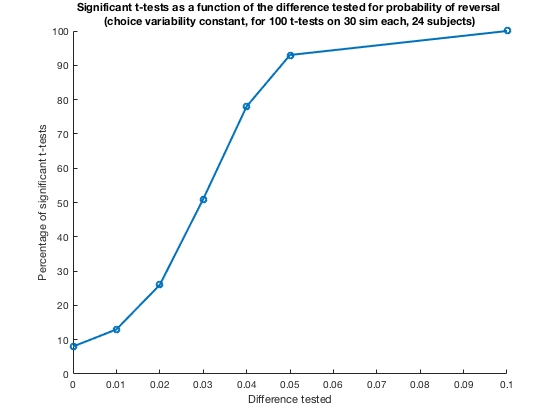

prevonly_diff_index = [1 2 3 4 5 6 7]    ; % to enter manually according to respective index in 'ndiff'
finalplots_mindiff(dout, nsubjsubset, nsim, nttest, ndiff, 1, prevonly_diff_index,     ...
                         prev_diffsigni_acrossdiff, 'probability of reversal', 'prev', ...
                         'choice variability')

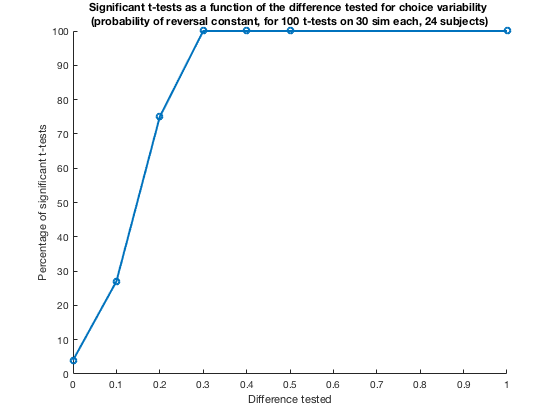

                         
betaonly_diff_index = [1 8 9 10 11 12 13]; % to enter manually according to respective index in 'ndiff'
finalplots_mindiff(dout, nsubjsubset, nsim, nttest, ndiff, 2, betaonly_diff_index,     ...
                         beta_diffsigni_acrossdiff, 'choice variability', 'beta',      ...
                         'probability of reversal')